# Obtaining model from step response

This script is responsible for obtaining an FOPT model from the step response of the DC motor, i.e., a first-order transfer function with delay using the areas method.

## Loading recorded data from the real motor

The step response data were recorded by providing a step input of 12V to the motor. The output represents the motor's speed expressed in RPM.

clear; close all; clc;

%% Loading data
data = load("matlab_speed_measures.mat");
speed=data.speed;

## Plot of the loaded data

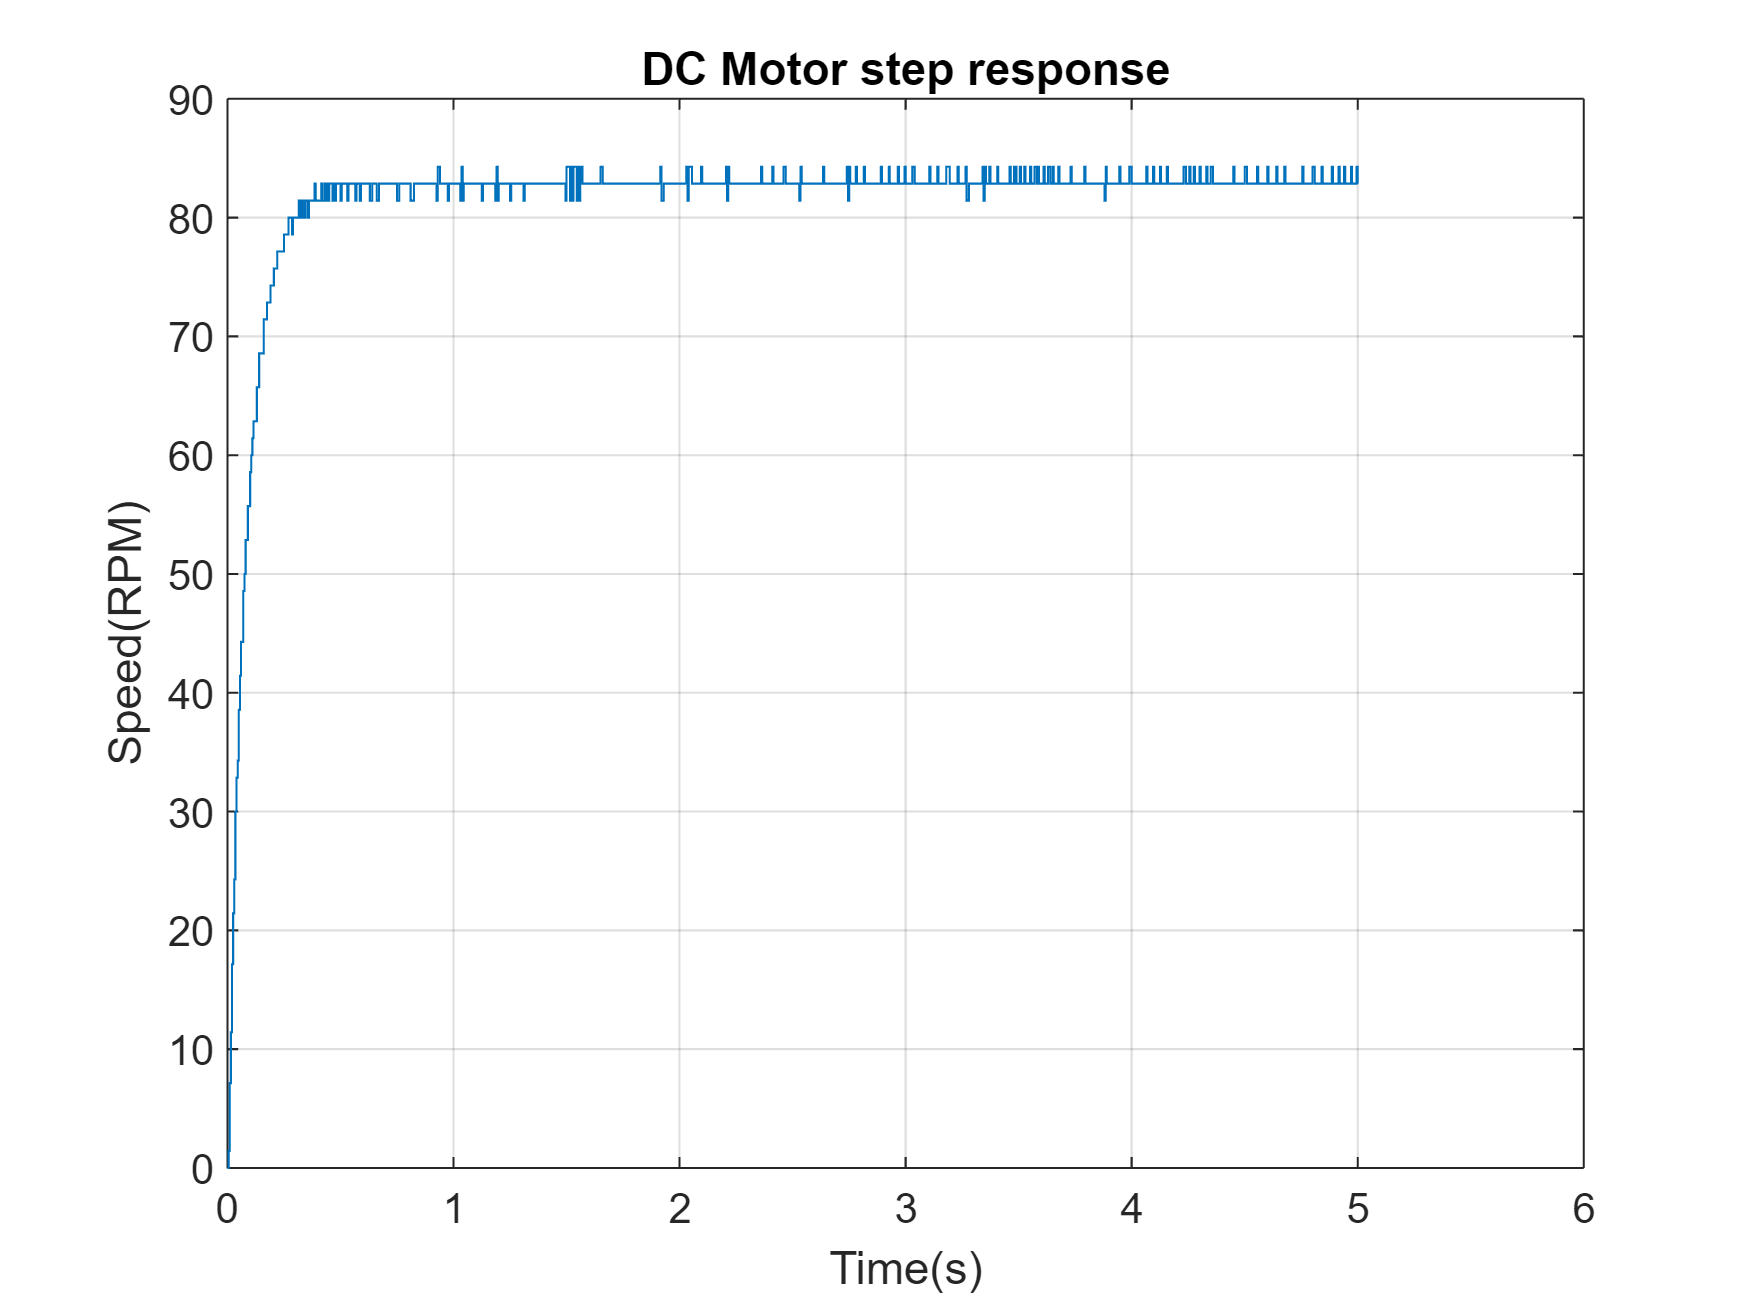

% Data plotting
plot(speed)

xlabel('Time(s)');
ylabel('Speed(RPM)');
title('DC Motor step response');
grid on;

## Application of the areas method

The previously loaded data was recorded for approximately 15 seconds. However, our interest lies in considering data up to a sufficiently long time to reach steady-state, plus a margin. Therefore, only the first 200 samples are considered. The steady-state output is calculated as the average value of the output once the system has reached steady-state, since the output, measured by the encoder, exhibits significant oscillations.

At this point, the areas S1 and S2 are calculated, which are functional to the application of the method.

%% Obtaining a model from a step response - Areas' approach
y=speed.data(1:200);
t = speed.time(1:200);
n=length(y);
y_ss = mean(speed.data(100:n));

[T_sol,tau_sol] =  AreasMethod(y,t,y_ss)

T_sol = 0.0908

tau_sol = -0.0042

s =
 
  s
 
Continuous-time transfer function.
Model Properties


T_sol = 0.0908

tau_sol = -0.0042


s = tf('s');

if tau_sol < 0
% It needs only because if this value is negative the plot of G return an error.
    tau = 0; 
else 
    tau=tau_sol;
end 

G = ((y_ss/12)/(1+T_sol*s))*exp(-tau*s)

G =
 
      6.893
  -------------
  0.09084 s + 1
 
Continuous-time transfer function.
Model Properties



[y_step,t_step] = step(12*G, 5);


## Data filtering

It was considered to filter the encoder output, although the areas method is robust against output noise. This is because the resulting value is negative, and it was assumed to be due to the oscillations. The filter considered is a moving average filter. Before calibrating it using the `windowSize` parameter, it was deemed appropriate to evaluate to what extent the delay introduced by the filter was affected by the value of this parameter.

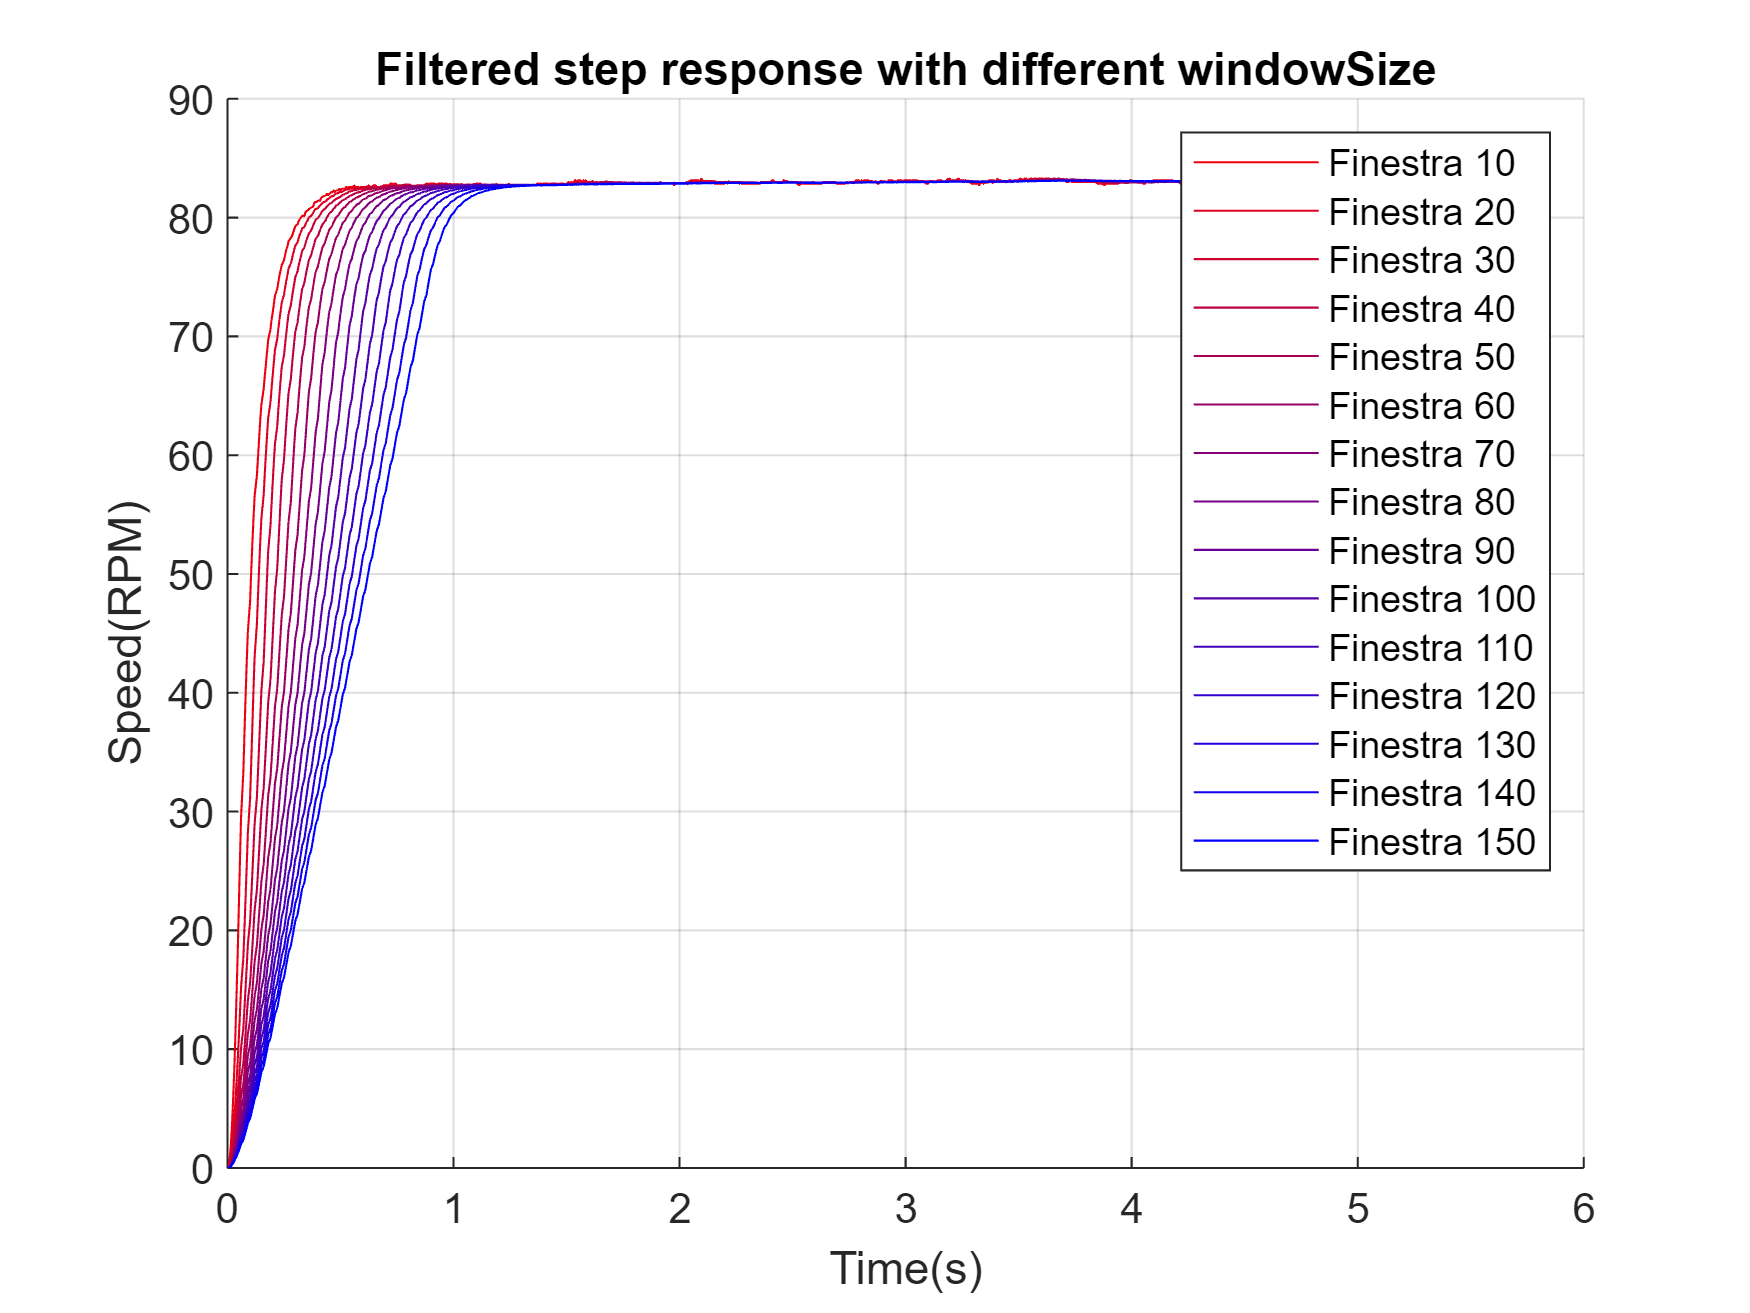

%% Check windowSize for data filtering
step_size = 25;
w_size = 10:10:150;

legendStrings = cell(1, length(w_size));  
figure
hold on;
grid on;
for i = 1:length(w_size)
    
    windowSize = round(w_size(i));  % Round to the nearest integer

    b = (1/windowSize)*ones(1,windowSize);
    a = 1;

    y = filter(b,a,speed.data);
    plot(speed.time, y, 'Color', [1-i/length(w_size), 0, i/length(w_size)]); 

    legendStrings{i} = ['Finestra ', num2str(windowSize)];
end

xlabel('Time(s)');
ylabel('Speed(RPM)');
title('Filtered step response with different windowSize');

% Aggiungi la legenda con le stringhe accumulate
legend(legendStrings);

hold off;

### Application of the area method on the filtered data

At this stage, the filter has been tuned to an appropriate size, and the area method has been reapplied to the filtered data. 

%% Data filtering
windowSize = 4; % The settling time remains nearly unchanged
b = (1/windowSize)*ones(1,windowSize);
a = 1;
y_filtered = filter(b,a,speed.data(1:200));

t=data.speed.time(1:200);
n=length(y_filtered)

n = 200

y_ss = mean(y_filtered(100:n))

y_ss = 82.7228


y_ss_filtered = mean(y_filtered(100:n));

[T_sol_filtered,tau_sol_filtered] =  AreasMethod(y_filtered,t,y_ss_filtered)

T_sol = 0.0945

tau_sol = 4.7651e-04

s =
 
  s
 
Continuous-time transfer function.
Model Properties


T_sol_filtered = 0.0945

tau_sol_filtered = 4.7651e-04


s = tf('s');

if tau_sol_filtered < 0
    tau_f = 0;
else 
    tau_f=tau_sol_filtered;
end 

G_filtered = (y_ss_filtered/12)/(1+T_sol_filtered*s)*exp(-tau_f*s)

G_filtered =
 
                         6.894
  exp(-0.000477*s) * -------------
                     0.09453 s + 1
 
Continuous-time transfer function.
Model Properties


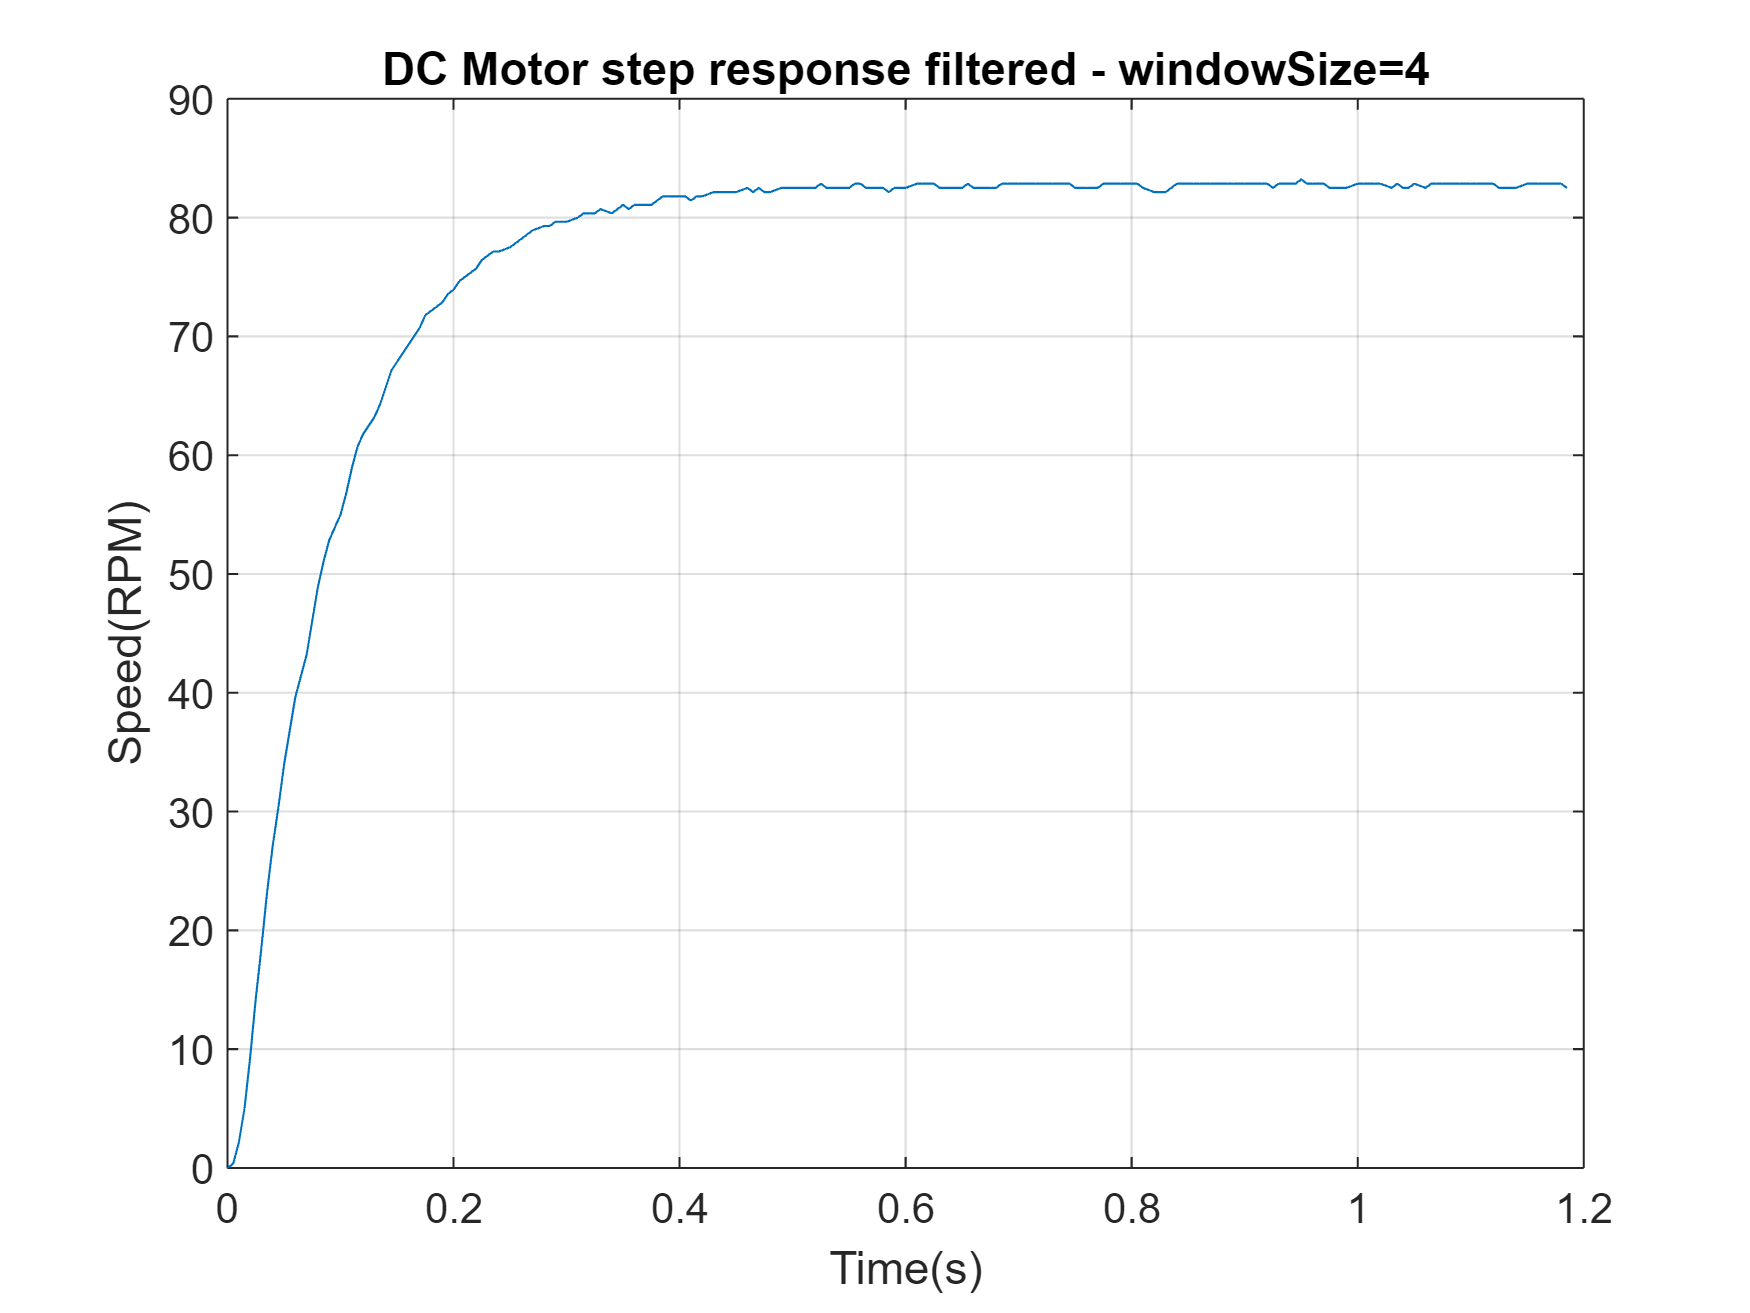

[y_step_f,t_step_f] = step(12*G_filtered, 5);

figure
plot(t, y_filtered)

xlabel('Time(s)');
ylabel('Speed(RPM)');
title('DC Motor step response filtered - windowSize=4');
grid on;

## Validation of the obtained models

Once the transfer function has been obtained using both the real data and the filtered data, the step response of each has been evaluated and compared with the real data to validate the goodness of the obtained model.

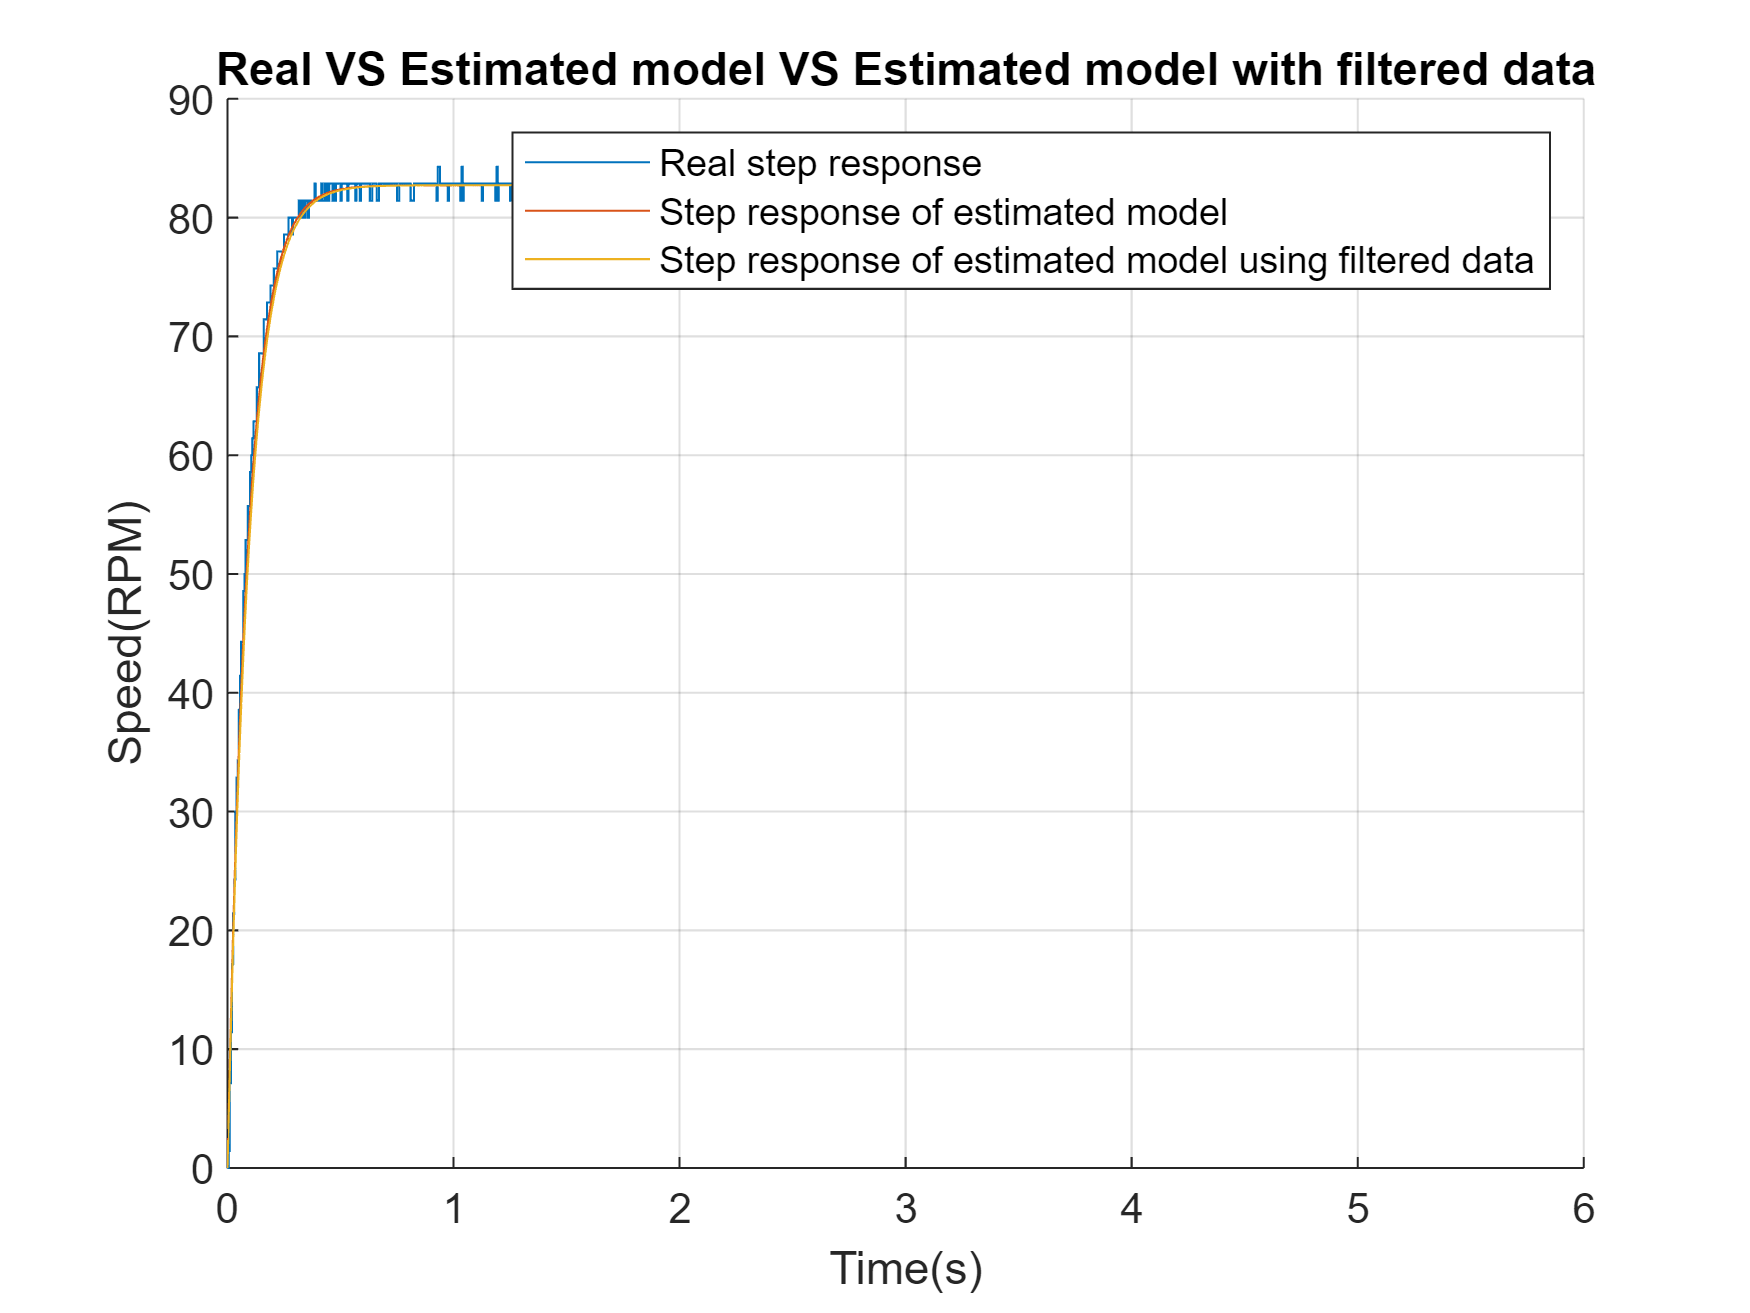


figure
hold on;
grid on;
plot(speed)
plot(t_step,y_step)
plot(t_step_f,y_step_f)

step_response_Strings{1} = ['Real step response'];
step_response_Strings{2} = ['Step response of estimated model'];
step_response_Strings{3} = ['Step response of estimated model using filtered data'];
legend(step_response_Strings);


xlabel('Time(s)');
ylabel('Speed(RPM)');
title('Real VS Estimated model VS Estimated model with filtered data');
hold off;

## Transfer function for position

The model obtained earlier pertains to velocity, but our focus is on position control. Consequently, a pole at the origin has been added to the transfer function obtained. The factor 9.5493 relates to the conversion between RPM and rad/s.

%% Transfer function for position control
G_pos = G * (1/(s*9.5493))

G_pos =
 
         6.893
  --------------------
  0.8675 s^2 + 9.549 s
 
Continuous-time transfer function.
Model Properties
